2. The robot body may be considered as still(same orientation as the Ground frame), so place all the intermediate frames until the foot. Fill in the table as asked in the first exercise. Write all the homogeneous transform matrices from a frame.

clc
clear

theta = sym('theta', [1 3]);
a = sym('L', [1 3]);

T01 = HM(a(1), -pi/2, 0, theta(1))

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & L_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & L_{1}\,\sin\left(\theta_{1}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = HM(a(2),  0,  0, theta(2))

$$T12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & L_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & L_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = HM(a(3),  0,  0, theta(3))

$$T23 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & L_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & L_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T03 = simplify(T01*T12*T23)

$$T03 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sigma_{1}\\ \cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sigma_{1}\\ -\sin\left(\theta_{2}+\theta_{3}\right) & -\cos\left(\theta_{2}+\theta_{3}\right) & 0 & -L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)-L_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{1}+L_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\cos\left(\theta_{2}\right) \end{array}$$

3. By using direct method, calculate the Jacobian matrix which give the foot motion relative to the ground frame.

X = T03(1:3,4);
Q = transpose(theta);
J=jacobian(X,Q)

$$J = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(\theta_{1}\right)\,\sigma_{2} & -\cos\left(\theta_{1}\right)\,\sigma_{1} & -L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\,\sigma_{2} & -\sin\left(\theta_{1}\right)\,\sigma_{1} & -L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)\\ 0 & -\sigma_{3}-L_{2}\,\cos\left(\theta_{2}\right) & -\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=L_{1}+\sigma_{3}+L_{2}\,\cos\left(\theta_{2}\right)\\ \sigma_{3}=L_{3}\,\cos\left(\theta_{2}+\theta_{3}\right) \end{array}$$

simplify(det(J))

$$ans = L_{2}\,L_{3}\,\left(L_{3}\,\sin\left(\theta_{2}\right)\,{\cos\left(\theta_{3}\right)}^{2}+L_{3}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\cos\left(\theta_{3}\right)+L_{1}\,\sin\left(\theta_{3}\right)-L_{3}\,\sin\left(\theta_{2}\right)+L_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\right)$$

% Jacobian 2
x = T03(1,4); 
y = T03(2,4);
z = T03(3,4);

% diff respect to x
J11 = diff(x, theta(1));
J12 = diff(x, theta(2));
J13 = diff(x, theta(3));

% diff respect to y
J21 = diff(y, theta(1));
J22 = diff(y, theta(2));
J23 = diff(y, theta(3));

% diff respect to z
J31 = diff(z, theta(1));
J32 = diff(z, theta(2));
J33 = diff(z, theta(3));


J = [ J11 J12 J13;
      J21 J22 J23;
      J31 J32 J33]

$$J = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(\theta_{1}\right)\,\sigma_{2} & -\cos\left(\theta_{1}\right)\,\sigma_{1} & -L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\,\sigma_{2} & -\sin\left(\theta_{1}\right)\,\sigma_{1} & -L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)\\ 0 & -\sigma_{3}-L_{2}\,\cos\left(\theta_{2}\right) & -\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=L_{1}+\sigma_{3}+L_{2}\,\cos\left(\theta_{2}\right)\\ \sigma_{3}=L_{3}\,\cos\left(\theta_{2}+\theta_{3}\right) \end{array}$$

rank(J)

ans = 3

simplify(det(J))

$$ans = L_{2}\,L_{3}\,\left(L_{3}\,\sin\left(\theta_{2}\right)\,{\cos\left(\theta_{3}\right)}^{2}+L_{3}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\cos\left(\theta_{3}\right)+L_{1}\,\sin\left(\theta_{3}\right)-L_{3}\,\sin\left(\theta_{2}\right)+L_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\right)$$

% jacobiana "Directa"

T02 = T01*T12

$$T02 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & L_{1}\,\cos\left(\theta_{1}\right)+L_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{1}\right) & L_{1}\,\sin\left(\theta_{1}\right)+L_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ -\sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right) & 0 & -L_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

simplify(T02)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sigma_{1}\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sigma_{1}\\ -\sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right) & 0 & -L_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{1}+L_{2}\,\cos\left(\theta_{2}\right) \end{array}$$


z0 = [0; 0; 1];  t0 = [0; 0; 0];
z1 = T01(1:3,3);
t1 = T01(1:3,4);
z2 = T02(1:3,3);
t2 = T02(1:3,4);
z3 = T03(1:3,3);
t3 = T03(1:3,4);
J = [cross(z0,t3-t0) cross(z1,t3-t1) cross(z2,t3-t2);
     z0 z1 z2];
simplify(J)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(\theta_{1}\right)\,\sigma_{2} & -\cos\left(\theta_{1}\right)\,\sigma_{1} & -L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\,\sigma_{2} & -\sin\left(\theta_{1}\right)\,\sigma_{1} & -L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)\\ 0 & -\sigma_{3}-L_{2}\,\cos\left(\theta_{2}\right) & -\sigma_{3}\\ 0 & -\sin\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\\ 0 & \cos\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\\ 1 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=L_{1}+\sigma_{3}+L_{2}\,\cos\left(\theta_{2}\right)\\ \sigma_{3}=L_{3}\,\cos\left(\theta_{2}+\theta_{3}\right) \end{array}$$



q1 = 90/180*pi;
q2 = 50/180*pi;
q3 = 90/180*pi;

L1 = 50;
L2 = 100;
L3 = 100;
J = [-sin(q1)*(L1 + L3*cos(q2 + q3) + L2*cos(q2)), -cos(q1)*(L3*sin(q2 + q3) + L2*sin(q2)), -L3*sin(q2 + q3)*cos(q1);
 cos(q1)*(L1 + L3*cos(q2 + q3) + L2*cos(q2)), -sin(q1)*(L3*sin(q2 + q3) + L2*sin(q2)), -L3*sin(q2 + q3)*sin(q1); 
 0, - L3*cos(q2 + q3) - L2*cos(q2), -L3*cos(q2 + q3);
 0, -sin(q1), -sin(q1);
 0, cos(q1), cos(q1);
 1, 0, 0]

J =   -37.6743   -0.0000   -0.0000
    0.0000 -140.8832  -64.2788
         0   12.3257   76.6044
         0   -1.0000   -1.0000
         0    0.0000    0.0000
    1.0000         0         0


rank(J)

ans = 3

det(J(1:3,:))

ans = 3.7674e+05

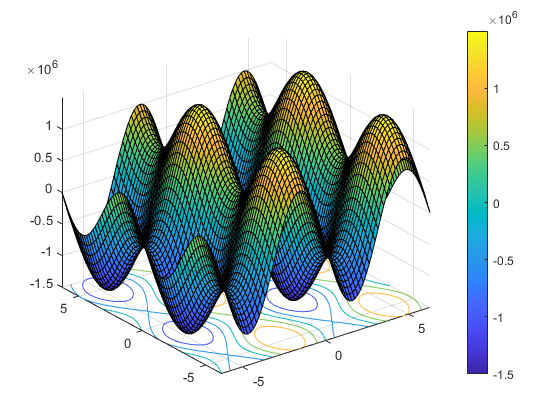

theta2 =-360:10:360;
theta3 = theta2;
[theta2,theta3] = meshgrid(theta2*pi/180,theta3*pi/180);
DJ= L2*L3*(L3*sin(theta2)*cos(theta3)^2 + L3*cos(theta2)*sin(theta3)*cos(theta3) + L1*sin(theta3) - L3*sin(theta2) + L2*cos(theta2)*sin(theta3));
surfc(theta2,theta3,DJ)
colorbar

DJ

DJ = 	1.0e+06 *

   -0.0000   -0.1736   -0.3420   -0.5000   -0.6428   -0.7660   -0.8660   -0.9397   -0.9848   -1.0000   -0.9848   -0.9397   -0.8660   -0.7660   -0.6428   -0.5000   -0.3420   -0.1736   -0.0000    0.1736    0.3420    0.5000    0.6428    0.7660    0.8660    0.9397    0.9848    1.0000    0.9848    0.9397    0.8660    0.7660    0.6428    0.5000    0.3420    0.1736   -0.0000   -0.1736   -0.3420   -0.5000   -0.6428   -0.7660   -0.8660   -0.9397   -0.9848   -1.0000   -0.9848   -0.9397   -0.8660   -0.7660
    0.0868   -0.0868   -0.2552   -0.4132   -0.5560   -0.6792   -0.7792   -0.8529   -0.8980   -0.9132   -0.8980   -0.8529   -0.7792   -0.6792   -0.5560   -0.4132   -0.2552   -0.0868    0.0868    0.2605    0.4288    0.5868    0.7296    0.8529    0.9528    1.0265    1.0716    1.0868    1.0716    1.0265    0.9528    0.8529    0.7296    0.5868    0.4288    0.2605    0.0868   -0.0868   -0.2552   -0.4132   -0.5560   -0.6792   -0.7792   -0.8529   -0.8980   -0.9132   -0.8980   -0.8529  